clc
clear
data_stall_1v = readmatrix("data_stall_1v.csv");
data_1v = readmatrix("data3_1v.csv");

V_stall = data_stall_1v(1, 7);
I_stall = data_stall_1v(100:end, 6);
R_stall = 1/mean(I_stall)

R_stall = 8.6500



syms J Km b Iss K tau R
eq1 = K == Km/(R*b+Km^2)

$$eq1 = K=\frac{\mathrm{Km}}{{\mathrm{Km}}^{2}+R\,b}$$

eq2 = tau == R*J/(R*b+Km^2)

$$eq2 = \tau =\frac{J\,R}{{\mathrm{Km}}^{2}+R\,b}$$

eq3 = Iss == b/(R*b+Km^2)

$$eq3 = \mathrm{Iss}=\frac{b}{{\mathrm{Km}}^{2}+R\,b}$$

t = data_1v(:, 1);
omega1 = data_1v(:, 4)

omega1 =          0
         0
   -0.0099
         0
         0
         0
    0.2979
    0.2979
    0.5182
    0.6867
    0.7445
    0.7445
    0.8391
    0.9349
    0.9799


omega1 = omega1*2

omega1 =          0
         0
   -0.0197
         0
         0
         0
    0.5958
    0.5958
    1.0365
    1.3734
    1.4889
    1.4889
    1.6781
    1.8698
    1.9597


figure
hold on
plot(t, omega1)
xlabel("t [s]")
ylabel("omega1 [rad/s]")

K_val = mean(omega1(t>10))

K_val = 18.6296

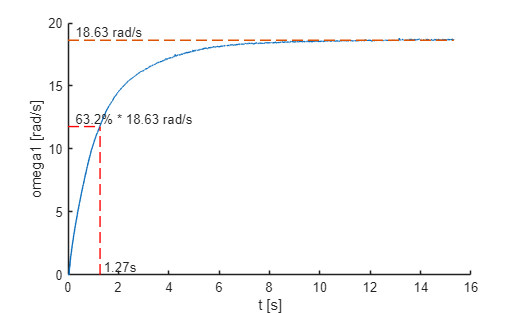

target = 0.632 * K_val;
idx = find(omega1 >= target, 1, 'first');
tau_est = t(idx);

plot([0, max(t)], [K_val, K_val], "--")
plot([0, tau_est], [K_val*0.632, K_val*0.632], "--", "Color","red")
plot([tau_est, tau_est], [0, K_val*0.632], "--", "Color","red")


text(0, K_val, sprintf('  %.2f rad/s', K_val), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left')
text(0, K_val*0.632, sprintf('  63.2%% * %.2f rad/s', K_val), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left')
text(tau_est, 0, sprintf(' %.2fs', tau_est), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left')
hold off

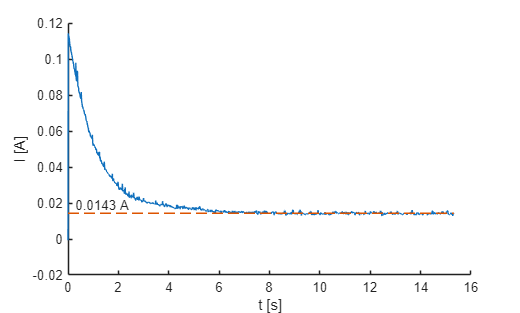


figure
hold on
current = data_1v(:, 6);
plot(t, current);
xlabel("t [s]")
ylabel("I [A]")
Iss_val = mean(current(t>8));

plot([0, max(t)], [Iss_val, Iss_val], "--")
text(0, Iss_val, sprintf('  %.4f A', Iss_val), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left')

eq = subs([eq1, eq2, eq3].', [R, Iss, K, tau], [R_stall, Iss_val, K_val, tau_est])

$$eq = \left(\begin{array}{c} \frac{5243762197982543}{281474976710656}=\frac{\mathrm{Km}}{{\mathrm{Km}}^{2}+\frac{4869494908777749\,b}{562949953421312}}\\ \frac{12729}{10000}=\frac{4869494908777749\,J}{562949953421312\,\left({\mathrm{Km}}^{2}+\frac{4869494908777749\,b}{562949953421312}\right)}\\ \frac{4122053685729877}{288230376151711744}=\frac{b}{{\mathrm{Km}}^{2}+\frac{4869494908777749\,b}{562949953421312}} \end{array}\right)$$

sol = solve(eq);
Km_sol = vpa(sol.Km, 4)

$$Km\_sol = 0.04704$$

J_sol = vpa(sol.J, 4)

$$J\_sol = 0.0003716$$

b_sol = vpa(sol.b, 4)

$$b\_sol = 3.611e-5$$

clc
clear
data_pendulum = readmatrix("data_pendulum.csv");
t_raw = data_pendulum(:, 1);
theta2_raw = data_pendulum(:, 3);

t = t_raw(t_raw>6);
%t = t(t_raw < 10);

theta2 = theta2_raw(t_raw>6);
%theta2 = theta2(t_raw < 10);


t = t - t(1);



L = 0.0113445;
m = 0.119;

% Find A for the solution
A = max(theta2)

A = 1.3714


% Find the peas and then gamma
[pks, locs] = findpeaks(theta2, t);
log_pks = log(pks);
p = polyfit(locs, log_pks, 1);
exponent = p(1)

exponent = -0.0277

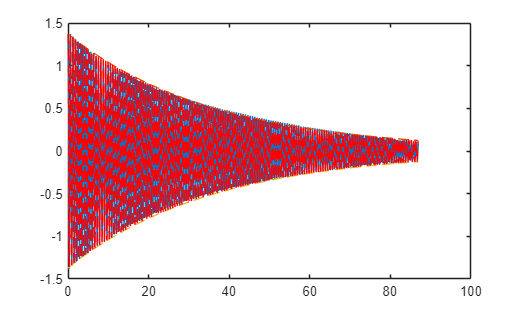


% Find the frequency
T = mean(diff(locs));
f = 1 / T;


figure
plot(t, theta2)
hold on
part1 = A*exp(exponent*t);
plot(t, part1, '--')
plot(t, -part1, '--')
part2 = cos(f*2*pi*t);
full = part1.*part2;
plot(t, part2.*part1, '--', 'Color', 'red');
hold off

syms b I wo
g = 9.82;


gamma = -2*exponent

gamma = 0.0554

wd = f*2*pi

wd = 10.7690

wo = sqrt(m*g*L/I)

$$wo = \sqrt{\frac{7642114719485841}{576460752303423488\,\text{I}}}$$

eq1 = gamma == b/I;
eq2 = wd == sqrt(wo^2-gamma^2/4);

eqs = [eq1, eq2].'

$$eqs = \left(\begin{array}{c} \frac{7981148999993793}{144115188075855872}=\frac{b}{\text{I}}\\ \frac{6062429063923293}{562949953421312}=\sqrt{\frac{7642114719485841}{576460752303423488\,\text{I}}-\frac{3535990353859093}{4611686018427387904}} \end{array}\right)$$

sol = solve(eqs, [b, I]);
b_sol = double(sol.b)

b_sol = 6.3306e-06

I_sol = double(sol.I)

I_sol = 1.1431e-04